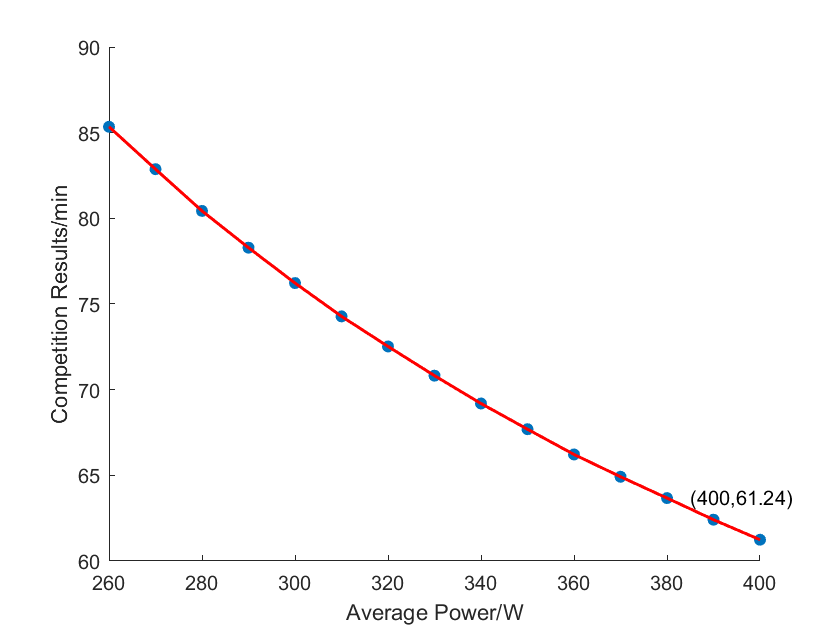

clear y
d=0;treal=55*60+4;
x1=log(mmt.r);y1=log(gp.r);
[L direction po]=Map(Mode);
for P = 200:10:500
    d=d+1;
    P2 = P*0.607;
    n = 1;
    [ob]=polyfit(x1,y1,n);
    % syms x y
    % eqn=log(y)==ob(1)*(log(x))+ob(2);
    y=P;
    x=exp((log(y)-ob(2))/ob(1));
    t3 = test1(P2,L,treal);
    if t3<x
        l3=1;
    else l3=0;
    end
    board(d,:)=[P t3 x l3];
end
n = 1:sum(board(:,4));
figure
scatter(board(n,1),board(n,2)/60*1.3,'filled');hold on
plot(board(n,1),board(n,2)/60*1.3,'r','LineWidth',1.5)
xlabel('Average Power/W' );ylabel('Competition Results/min')
Pi = max(board(n,1));
ob=['(',num2str(Pi),',',num2str(roundn(min(board(n,2)/60*1.3),-2)),')'];
text(max(board(n,1))-15,min(board(n,2)/60*1.3+2.5),ob);

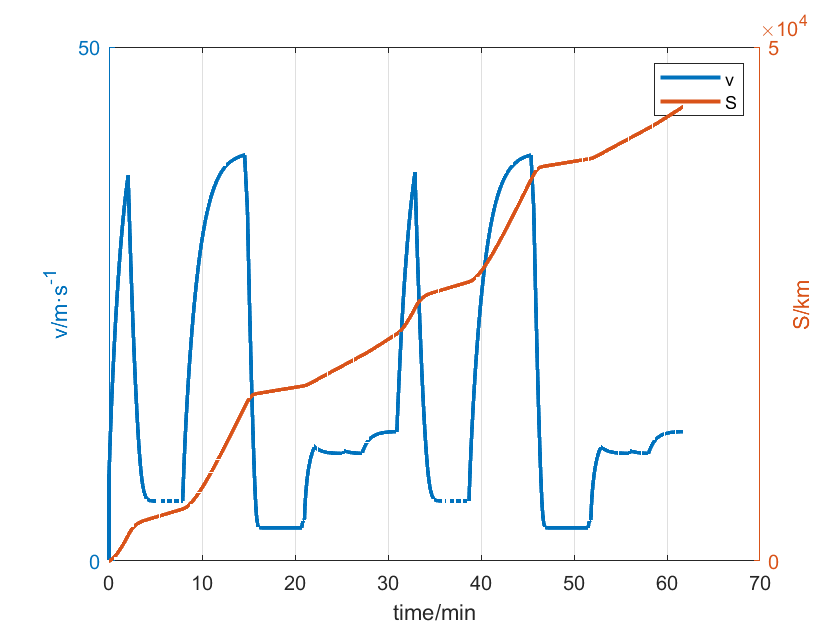


[ans v S t1 I]= test1(Pi*0.6,L,treal) ;
ti=(t1.a:t1.b:t1.end)/60*1.3;
figure;
[Y,H1,H2]=plotyy(ti,v,ti,S);
legend('v','S')
xlabel('time/min');
set(get(Y(1),'ylabel'),'string', 'v/m·s^{-1}');%,'fontsize',16
set(get(Y(2),'ylabel'),'string', 'S/km');
set(H1,'LineWidth',2 );%,'fontsize',16
set(H2,'LineWidth',2 );%,'fontsize',16
grid on;

res1 = res (Mode,I,S,t1,L)

res1 = 	1.0e+04 *

    0.0003    0.5045    1.4990    1.5485    1.7033    2.2083    3.7075    3.7563    3.9111    4.4160
   -0.0001    0.0001   -0.0001         0    0.0001         0   -0.0001         0    0.0001         0
    0.0026    0.0009    0.0032    0.0037    0.0005    0.0011    0.0023    0.0037    0.0009    0.0009
    0.0095    0.0271    0.0307    0.0014    0.0283    0.0459    0.0665    0.0014    0.0284    0.0459
